# Lab 02

## Syed Asad Ali

#### sa09475

## Task 1a

x = 15.5 + 3.175i

x = 15.5000 + 3.1750i

r1=real(x) %real value

r1 = 15.5000

i1 = imag(x) %imaginary value

i1 = 3.1750

c1=conj(x) %complex conjugate

c1 = 15.5000 - 3.1750i

a1 = abs(x) %magnitude

a1 = 15.8218

p1 = angle(x)  %phase angle

p1 = 0.2020

## Task 1b

[r, im]=pol2cart(45*pi/100, 5)

r = 0.7822

im = 4.9384

x1=r +im*j

x1 = 0.7822 + 4.9384i

r2=real(x1) %real value

r2 = 0.7822

i2 = imag(x1) %imaginary value

i2 = 4.9384

c2=conj(x1) %complex conjugate

c2 = 0.7822 - 4.9384i

a2 = abs(x1) %magnitude

a2 = 5.0000

p2 = angle(x1)  %phase angle

p2 = 1.4137

## Try 1

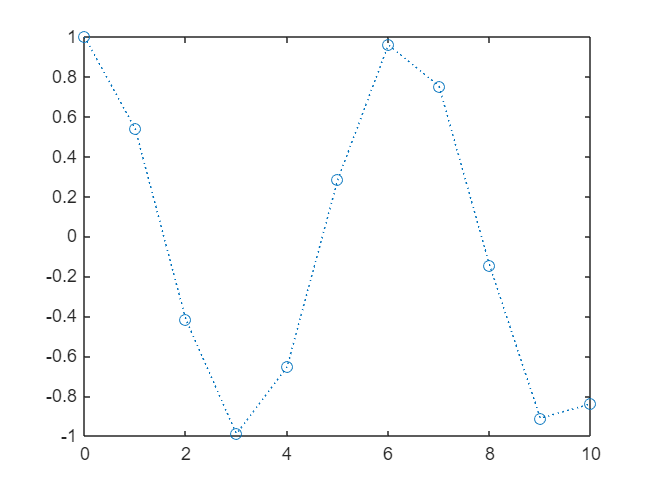

n = 0:10;
y = cos(n); 
figure; plot(n, y, ':o');

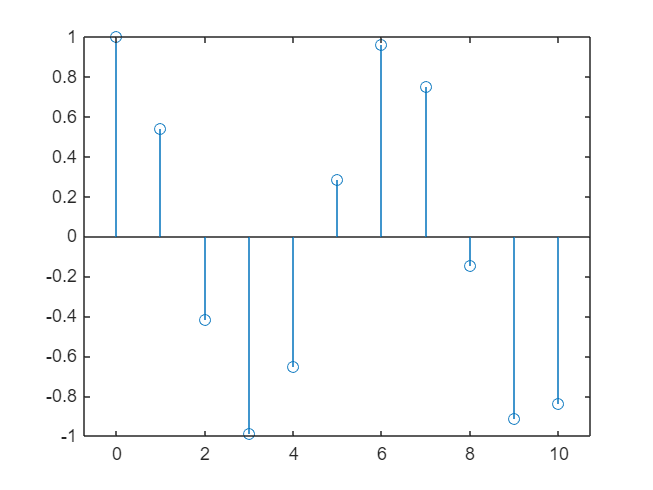

figure; stem(n, y);

## Try 2

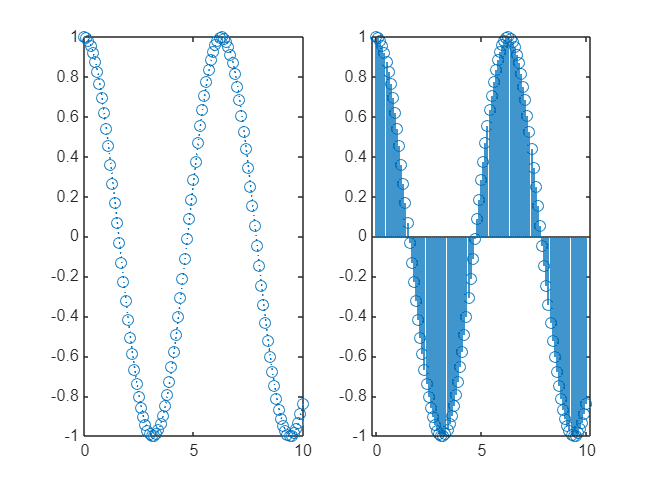

Ts = 0.1;	% Defining sampling time, the time interval between two consecutive samples
Fs = 1/Ts;	% Defining sampling frequency, the number of samples per second
t = 0:Ts:10;	% Defining time span	
y = cos(t); 	% Obtaining a discrete-time signal
figure; 	% Using subplots to depict two plots in one figure
subplot 121; plot(t, y, ':o'); 	
subplot 122; stem(t, y);

## Task 2a

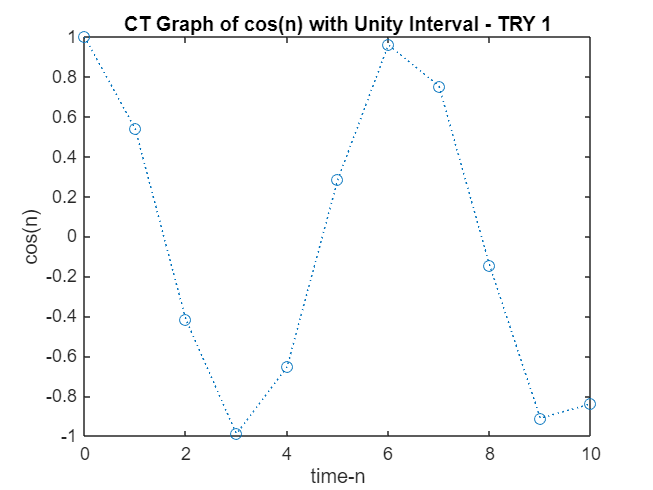

n = 0:10;
y = cos(n); 
figure; plot(n, y, ':o');title('CT Graph of cos(n) with Unity Interval - TRY 1')
xlabel('time-n')
ylabel('cos(n)')

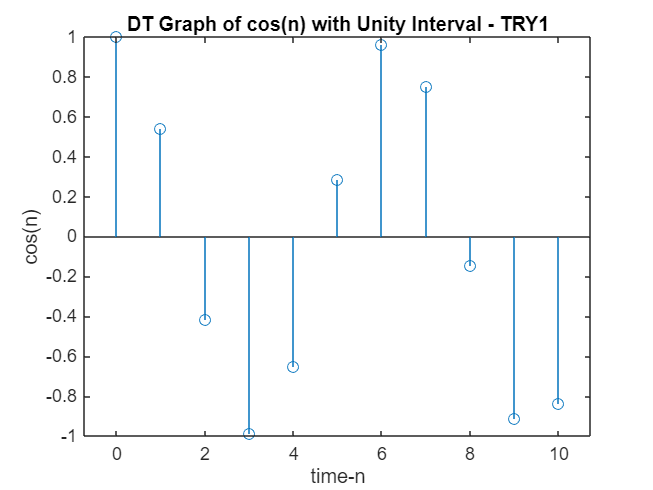


stem(n, y)
title('DT Graph of cos(n) with Unity Interval - TRY1')
xlabel('time-n')
ylabel('cos(n)')

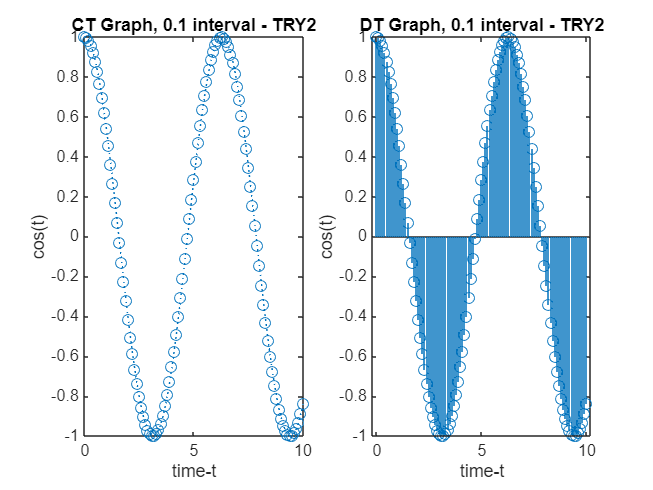


Ts = 0.1;
Fs = 1/Ts;
t = 0:Ts:10;
y = cos(t);
subplot 121;
plot(t, y, ':o')
title('CT Graph, 0.1 interval - TRY2')
xlabel('time-t')
ylabel('cos(t)')
subplot 122;
stem(t,y)
title('DT Graph, 0.1 interval - TRY2')
xlabel('time-t')
ylabel('cos(t)')

## Task 2b

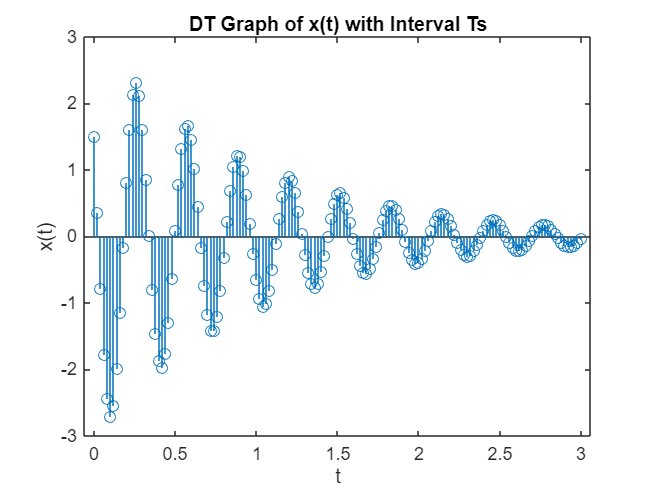

Fs = 50; %50hz ;
Ts = 1/Fs;
t = 0:Ts:3;
x = 3* exp(-t) .*cos(20*t + pi/3);
figure;
stem(t, x)
title('DT Graph of x(t) with Interval Ts')
xlabel('t')
ylabel('x(t)')

## Try 3

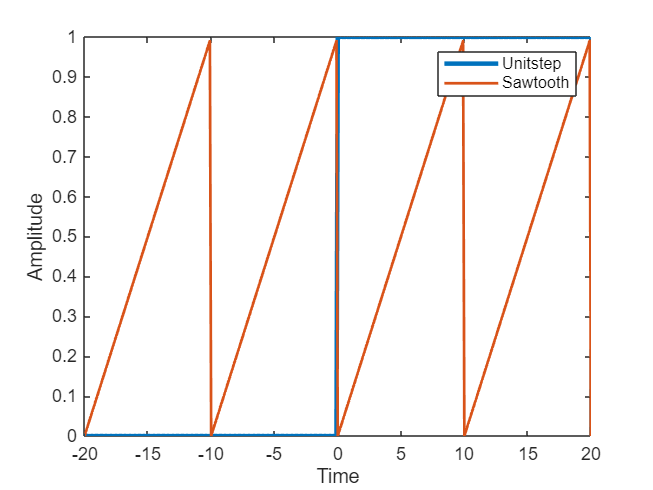

clc; 
clear
t = -20:0.1:20;
unitstep = t>= 0; % getting 1 when t is positive
s = 0.5*(sawtooth(2*pi*0.1*t)+1); % applying transformations to make the graph start from the origin and have 1 amplitude
figure;
plot(t, unitstep,'linewidth', 2.5)
xlabel('Time');
ylabel('Amplitude');
hold on; %retains plots in the current axes so that new plots added to the axes do not delete existing plots
plot(t, s,'linewidth', 1.5)
xlabel('Time');
ylabel('Amplitude');
xlim([-20 20]) % limits of time
ylim([0 1]) % limits of the amplitude of the graphs
legend('Unitstep','Sawtooth')
hold off;

## Task 3

clc; clear
t = -20:0.1:20;
unitstep = t>= 0; % getting 1 when t is positive
s = 0.5*(sawtooth(2*pi*0.1*t)+1); % applying transformations to make the graph start from the origin and have 1 amplitude
figure;
plot(t, unitstep,'linewidth', 2.5)
xlabel('Time');
ylabel('Amplitude');
hold on;
plot(t, s,'linewidth', 1.5)
xlabel('Time');
ylabel('Amplitude');
xlim([-20 20]) % limits of time
ylim([0 1]) % limits of the amplitude of the graphs
legend('Unitstep','Sawtooth')
hold off;

## Task 4

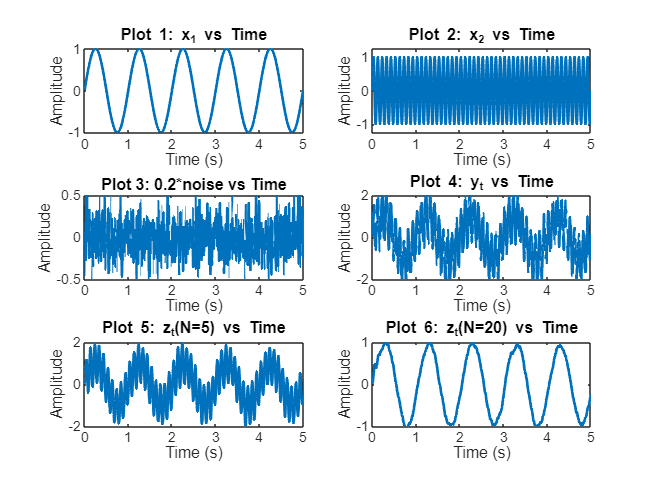

% Time scale: 0 to 5 seconds with interval of 0.005
t = 0:0.005:5;

% Frequencies
f1 = 1;  % Frequency of first sinusoid (1 Hz)
f2 = 10; % Frequency of second sinusoid (10 Hz)

% Generate two unit-amplitude sinusoids
xt1 = sin(2*pi*f1*t); % Sinusoid with frequency f1
xt2 = sin(2*pi*f2*t); % Sinusoid with frequency f2

% Generate noise with the same number of elements as xt1/xt2
noise = randn(size(t)); % Random noise

% Combine signals with noise
yt = xt1 + xt2 + 0.2*noise; % Resulting noisy signal

% Filtered signals
N1 = 5; % Number of samples for averaging filter (N=5)
zt1 = filter(ones(1, N1)/N1, 1, yt); % Filtered output for N=5

N2 = 20; % Number of samples for averaging filter (N=20)
zt2 = filter(ones(1, N2)/N2, 1, yt); % Filtered output for N=20

% Plotting
figure;

% Plot 1: xt1 versus time
subplot(3, 2, 1); % Position (1st row, 1st column)
plot(t, xt1, 'LineWidth', 1.5); % Plot the first signal
title('Plot 1: x_1 vs Time');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 5])
ylim([-1 1])

% Plot 2: xt2 versus time
subplot(3, 2, 2); % Position (1st row, 2nd column)
plot(t, xt2, 'LineWidth', 1.5); % Plot the second signal
title('Plot 2: x_2 vs Time');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 5])
ylim([-1.25 1.25])

% Plot 3: 0.2*noise versus time
subplot(3, 2, 3); % Position (2nd row, 1st column)
plot(t, 0.2*noise, 'LineWidth', 1.5); % Plot the noise signal
title('Plot 3: 0.2*noise vs Time');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 5])
ylim([-0.5 0.5])

% Plot 4: yt versus time
subplot(3, 2, 4); % Position (2nd row, 2nd column)
plot(t, yt, 'LineWidth', 1.5); % Plot the noisy signal
title('Plot 4: y_t vs Time');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 5])
ylim([-2 2])

% Plot 5: zt for N=5 versus time
subplot(3, 2, 5); % Position (3rd row, 1st column)
plot(t, zt1, 'LineWidth', 1.5); % Plot the filtered signal (N=5)
title('Plot 5: z_t(N=5) vs Time');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 5])
ylim([-2 2])

% Plot 6: zt for N=20 versus time
subplot(3, 2, 6); % Position (3rd row, 2nd column)
plot(t, zt2, 'LineWidth', 1.5); % Plot the filtered signal (N=20)
title('Plot 6: z_t(N=20) vs Time');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 5])
ylim([-1 1])

## Task 5-1a

x = 10.09 + 55.3i;
d = deg2rad(85.5); %converting to rad
[a,b] = pol2cart(d,20); %using funct to convert to rad
u = a+ 1i*b; % converting into a complex no using different functions to calc real,
c=x+u

c = 11.6592 +75.2383i

r3=real(c) %real value

r3 = 11.6592

i3 = imag(c) %imaginary value

i3 = 75.2383

c3=conj(c) %complex conjugate

c3 = 11.6592 -75.2383i

a3 = abs(c) %magnitude

a3 = 76.1364

p3 = angle(c)  %phase angle

p3 = 1.4171

## Task 5-1b

x = -4+10i;
q = deg2rad(10); %converting to rad
[a,b] = pol2cart(q,15); %using funct to convert to rad
u = a+ 1i*b; % converting into a complex no
%using different functions to calc real,
d= u+x;
r4=real(d) %real value

r4 = 10.7721

i4 = imag(d) %imaginary value

i4 = 12.6047

c4=conj(d) %complex conjugate

c4 = 10.7721 -12.6047i

a4 = abs(d) %magnitude

a4 = 16.5806

p4 = angle(d)  %phase angle

p4 = 0.8636

## Task 5-2

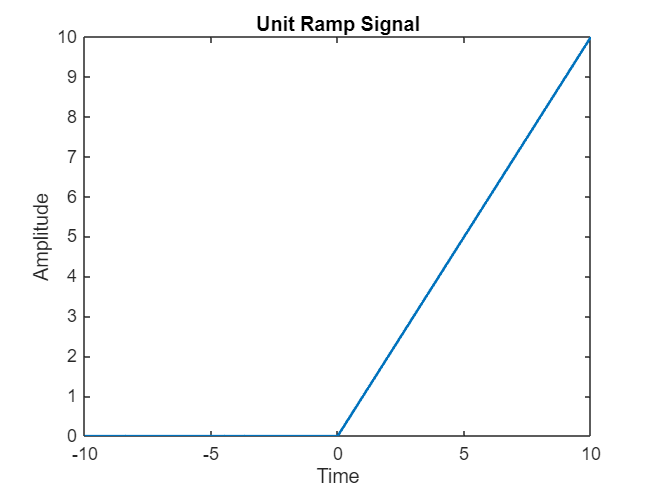

t = -10:0.01:10; % defining time
%unit ramp signals t*1 when t>0
r = t .* (t >= 0);
% Plot the unit ramp signal
figure;
plot(t, r, 'LineWidth', 1.5);
title('Unit Ramp Signal');
xlabel('Time');
ylabel('Amplitude');

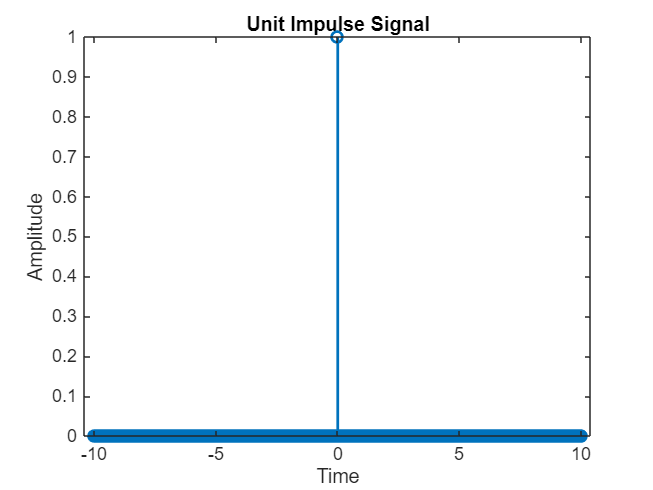


t = -10:0.01:10; % defining time
i = (t==0); %is one when time would be 0 else 0
figure;
stem(t, i, 'LineWidth', 1.5);
title('Unit Impulse Signal');
xlabel('Time');
ylabel('Amplitude');

## Task 6

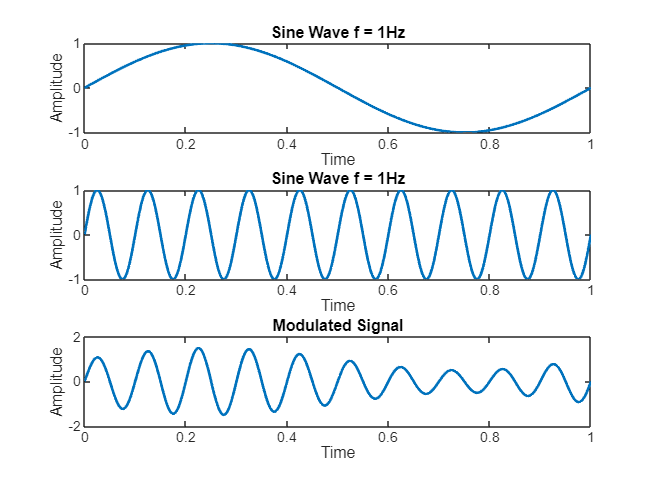

clc;
clear;
t = 0:0.001:1;
fm = 1;
fc = 10;
Am = 1;
Ac = 1;
mt = Am * sin(2*pi*fm*t);
ct = Ac*sin(2*pi*fc*t);
st = (1+ 0.5*mt) .* (ct);
figure;
subplot(3, 1, 1);
plot(t, mt, 'LineWidth', 1.5);
title("Sine Wave f = 1Hz");
xlabel("Time");
ylabel('Amplitude');
subplot(3, 1, 2);
plot(t, ct, 'LineWidth', 1.5);
title("Sine Wave f = 1Hz");
xlabel("Time");
ylabel('Amplitude');
subplot(3, 1, 3);
plot(t, st, 'LineWidth', 1.5);
title("Modulated Signal");
xlabel("Time");
ylabel('Amplitude');